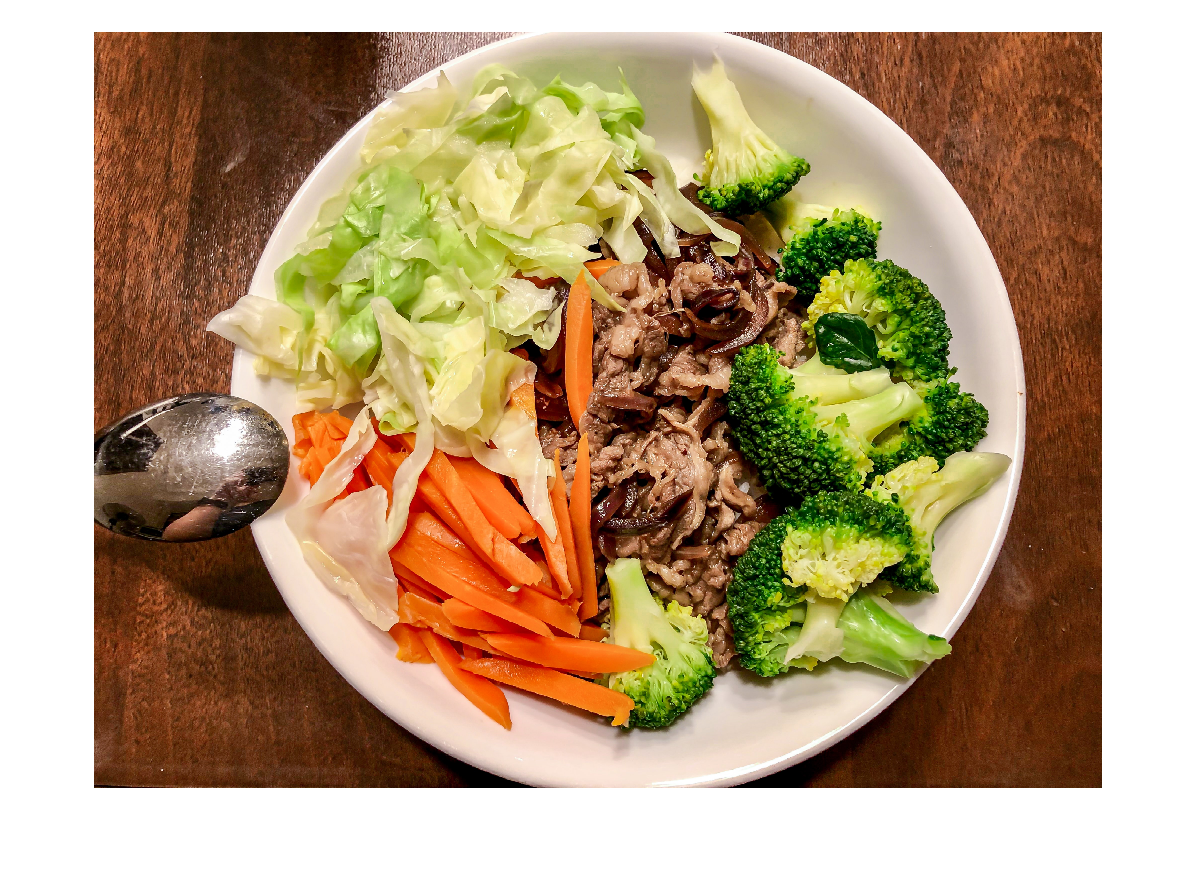

%%Project food classification document
%%This will contain the actual code we will use
%%Martin Iversen 
%%05.04.2021

%%Reads the image
image = imread('images/hard/Test26.jpg');

imshow(image)

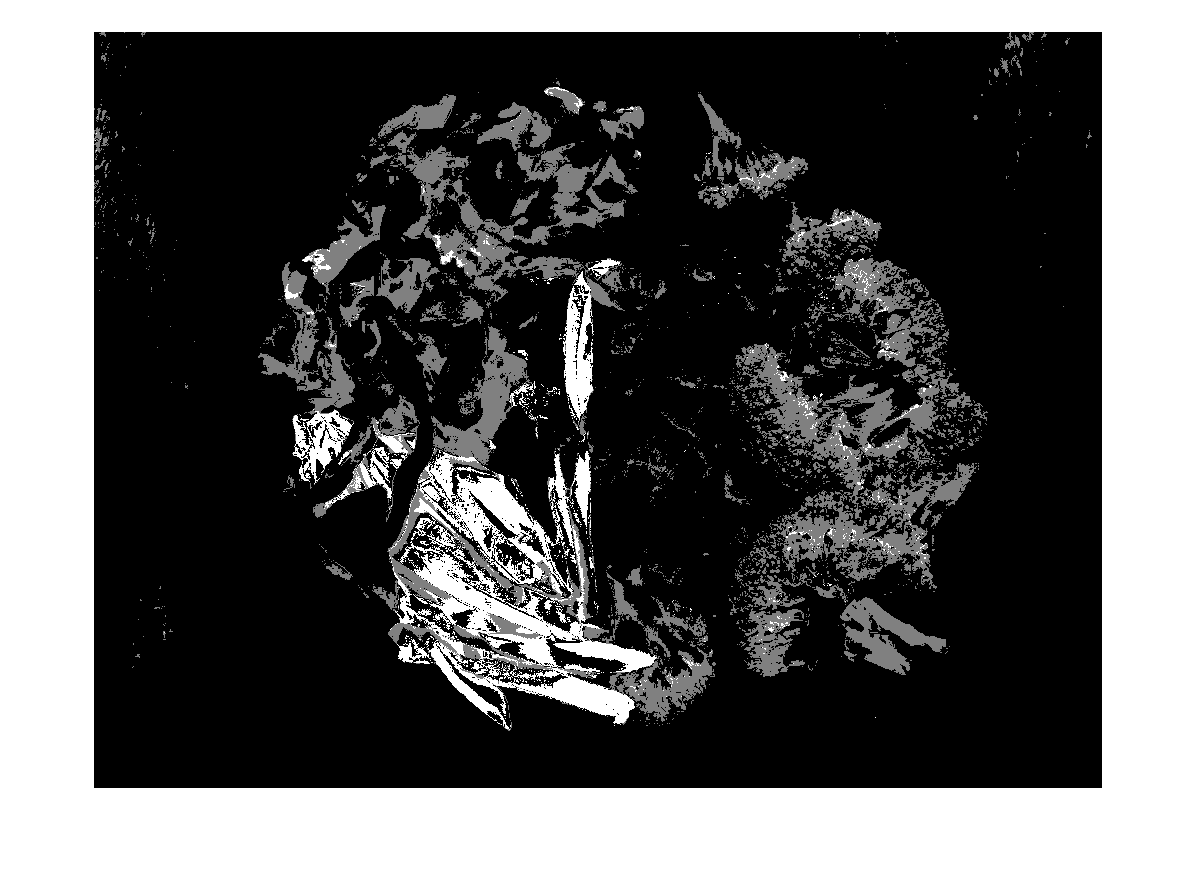


%%Defines the different binary masks for the images based on color
green = Green(image);        
lightGreen = LightGreen(image);
red = MoreRed(image);
yellow = Yellow(image);
purple = Purple(image);
orange = Orange(image);

%%Fuses both green masks to cover as much green as possible
greenResult = imfuse(lightGreen,green,'blend');

%%Fuses all of the masks together with diff 
result = imfuse(greenResult, red,'diff');
result = imfuse(yellow,result,'diff');
result = imfuse(purple,result,'diff');
result = imfuse(orange, result,'diff');

imshow(result)

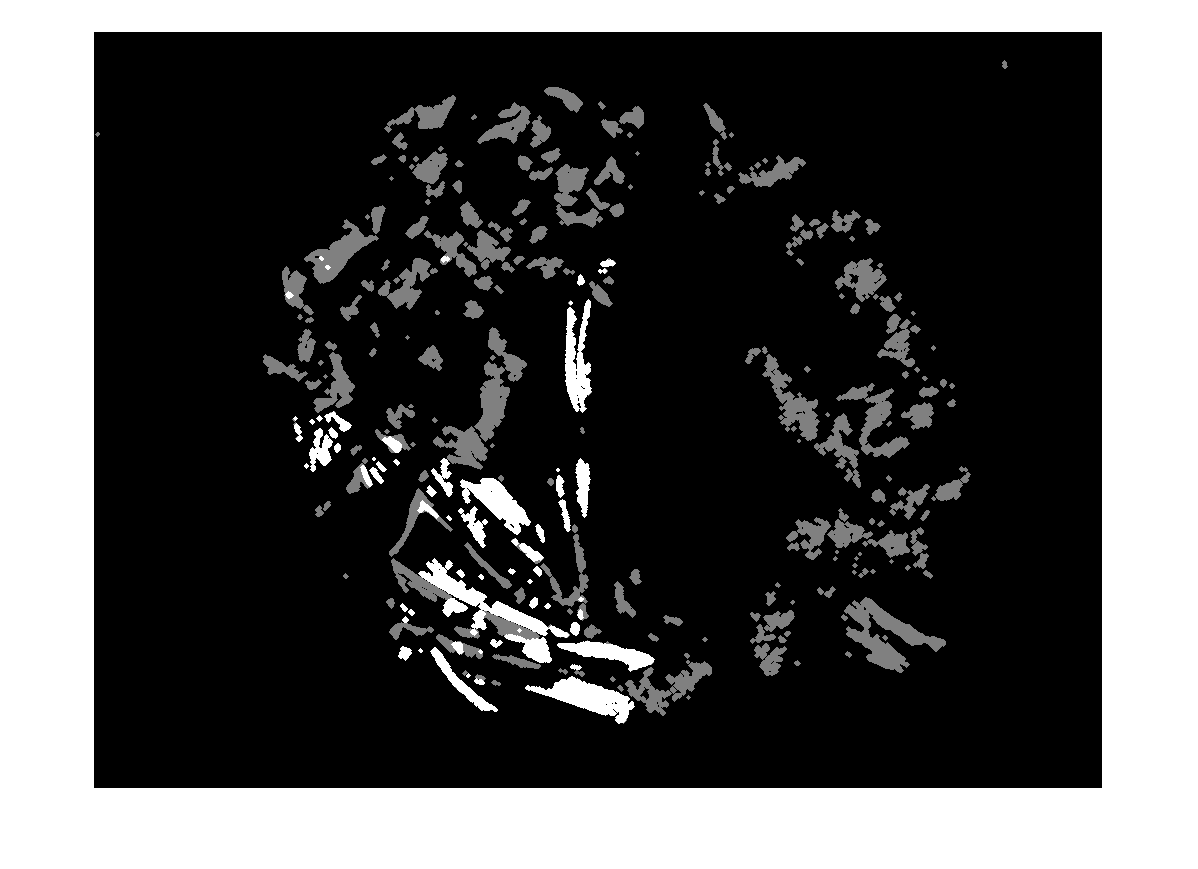


%%Defines a morphological structuring object
rough = strel('diamond',10);

%%Perform morphological opening on the image
roughProcessed = imopen(result,rough);
imshow(roughProcessed)

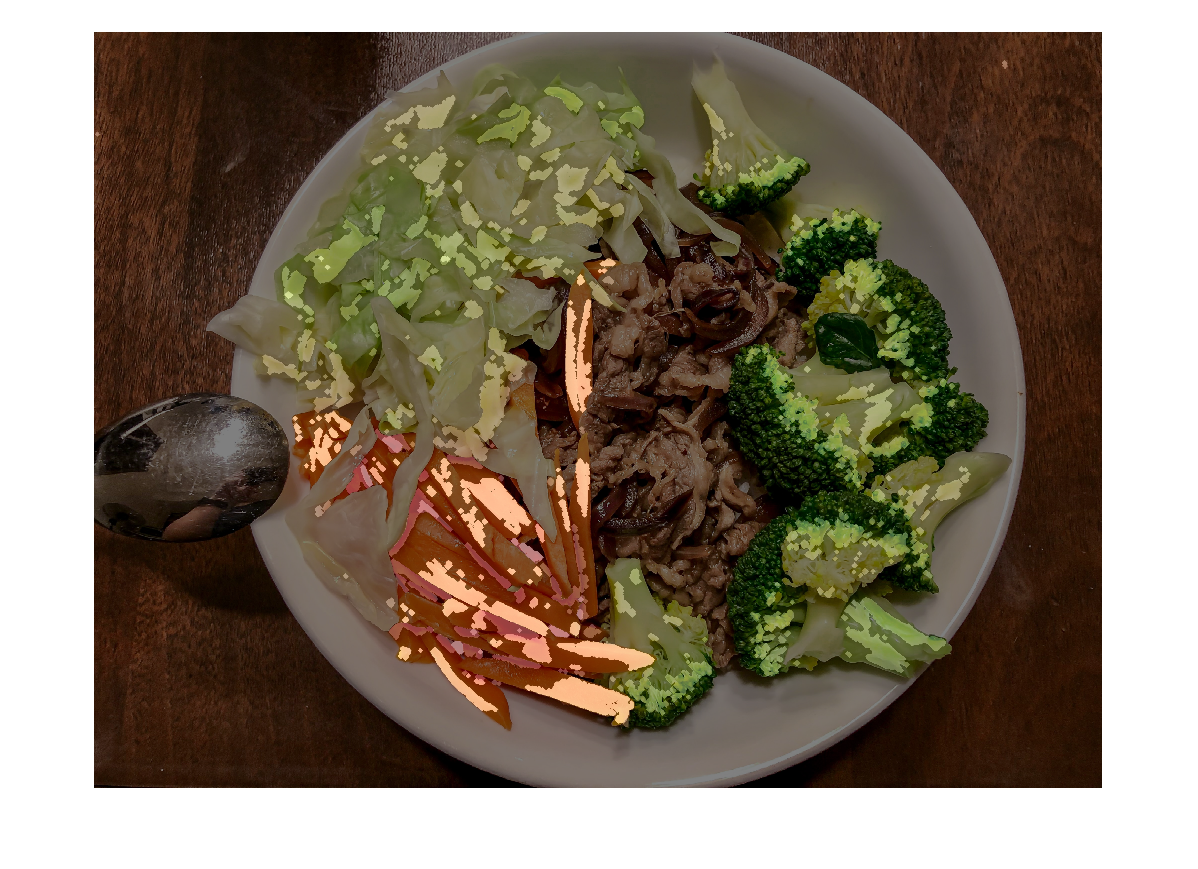


fused = imfuse(image,roughProcessed,'blend');

%%Display the images
imshow(fused)